Inicializácia

n0 = 1;%index prveho suboru
n = 6;%pocet suborov


Vykreslenie nameraných dát

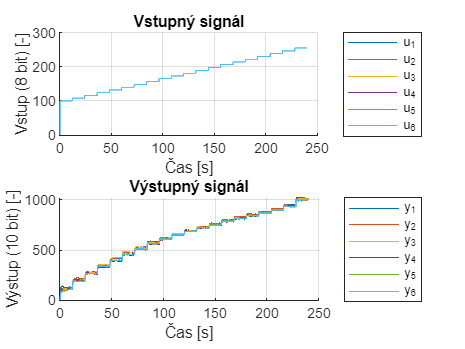

figure;
for i=n0:n0+n-1
    fileName = ['./../TP-PlainData/allSig_log_prev_mer',num2str(i),'_up.csv'];
    dt = csvread(fileName);
    subplot(2,1,1);
    txt = ['u_',num2str(i)];
    hold on;
    plot(dt(:,1),dt(:,2),'DisplayName',txt);
    hold off;
    subplot(2,1,2);
    txt = ['y_',num2str(i)];
    hold on;
    plot(dt(:,1),dt(:,3),'DisplayName',txt);
    hold off;
end
subplot(2,1,1);
grid on; 
title('Vstupný signál');
legend("Location",'bestoutside');
xlabel('Čas [s]');ylabel('Vstup (8 bit) [-]');
subplot(2,1,2);
grid on; 
title('Výstupný signál');
legend("Location",'bestoutside');
xlabel('Čas [s]');ylabel('Výstup (10 bit) [-]');

Získanie ustálených hodnôt výstupu z nameraných dát

m = 19;%predpoklad pocet derivacii vstupu (zmeny vstupu)
w = 400;%Pocet dat povaz ako ustalene
dataStore = zeros((m+1)*w,n+2);
for i=1:n
    fileName = ['./../TP-PlainData/allSig_log_prev_mer',num2str((n0-1)+i),'_up.csv'];
    dt = csvread(fileName);
    %dt = dt(2:end,:);
    diffVal = diff(dt(2:end,2));
    ids = find(or(diffVal > 0,diffVal < 0));    
    ln = size(ids,1);
    if ln == m
        ln = size(dt,1);
        id = [ids;ln];
        for j=1:m+1
            if i == 1
                dataStore(1+w*(j-1):w*j,1) = dt(id(j)-(w-1):id(j),1);  
                dataStore(1+w*(j-1):w*j,2) = dt(id(j)-(w-1):id(j),2);  
            end
            dataStore(1+w*(j-1):w*j,i+2) =  dt(id(j)-(w-1):id(j),3);
        end  
    end
end

Vykreslenie získaných ustálených dát

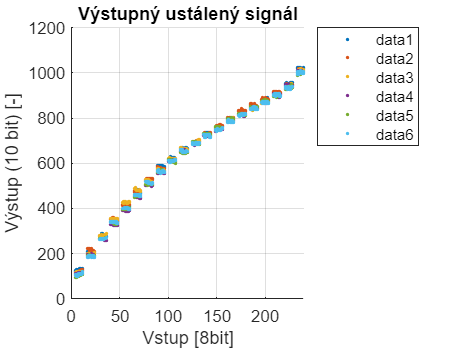

figure;
hold on;
for i=1:n
    plot(dataStore(:,1), dataStore(:,2+i),'.');
end
hold off;
grid on; 
title('Výstupný ustálený signál');
legend("Location",'bestoutside');
xlabel('Vstup [8bit]');ylabel('Výstup (10 bit) [-]');

Spriemerovanie získaných nameraných dát

Horizontálne priemerovanie

dataMean = zeros(m+1,n+1);
for i=1:n+1
    for j=1:m+1     
        if i == 1            
            dataToMean = dataStore(1+w*(j-1):w*j-1,i+1);
            dataMean(j,i) = mean(dataToMean);
        else
            dataToMean = dataStore(1+w*(j-1):w*j-1,i+1);
            dataMean(j,i) = mean(dataToMean);
        end        
    end
end

Vertikálne spriemerovanie

dataFullMean = zeros(m+1,2);
dataFullMean(:,1) = dataMean(:,1);
dt = dataMean(:,2:end)';
dataFullMean(:,2) = mean(dt);

Polyfit a polyder


[p, S] = polyfit(dataFullMean(:,1),dataFullMean(:,2),4);
[q,d] = polyder(p);
x1 = linspace(0,250,1000);
[y1,delta] = polyval(p,x1,S);
y2 = polyval(q/d,x1);

Vykreslenie

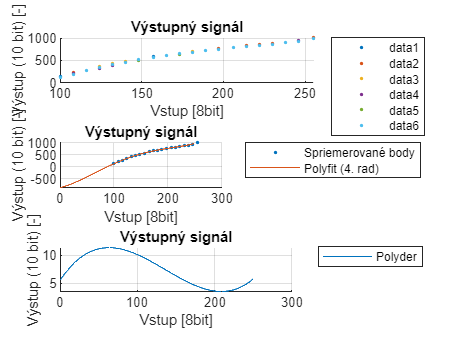

figure;
subplot(3,1,1);
hold on;
for i=1:n
    plot(dataMean(:,1), dataMean(:,1+i),'.');
end
hold off;
grid on; 
title('Výstupný signál');
legend("Location",'bestoutside');
xlabel('Vstup [8bit]');ylabel('Výstup (10 bit) [-]');
subplot(3,1,2);
hold on;
plot(dataFullMean(:,1),dataFullMean(:,2),'.','DisplayName','Spriemerované body')
plot(x1,y1,'DisplayName','Polyfit (4. rad)');
hold off;
grid on; 
title('Výstupný signál');
legend("Location",'bestoutside');
xlabel('Vstup [8bit]');ylabel('Výstup (10 bit) [-]');
subplot(3,1,3);
hold on;
plot(x1,y2,'DisplayName','Polyder');
hold off;
grid on; 
title('Výstupný signál');
legend("Location",'bestoutside');
xlabel('Vstup [8bit]');ylabel('Výstup (10 bit) [-]');

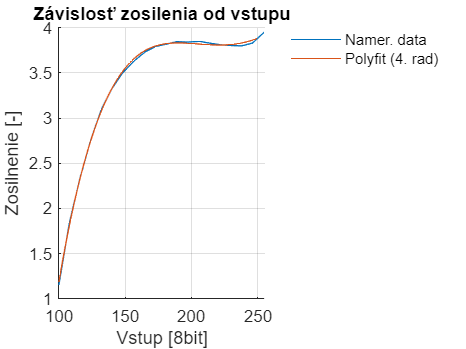

gainData = dataFullMean(:,2)./dataFullMean(:,1);
[pGain, SGain] = polyfit(dataFullMean(:,1),gainData,4);
x1 = linspace(100,250,151);
[y1,delta] = polyval(pGain,x1,SGain);

clf;
hold on;
plot(dataFullMean(:,1),gainData, 'DisplayName', 'Namer. data'); 
plot(x1,y1,'DisplayName','Polyfit (4. rad)');
hold off;
title('Závislosť zosilenia od vstupu');
legend('Location','bestoutside'); grid on; legend boxoff;
xlabel('Vstup [8bit]');ylabel('Zosilnenie [-]');